Tuning the z value

s = tf('s');
m = 27E-03;
Kt = 1.06e-5;
Tm = 0.02;

%Gs = 1/(m*s^2);
Gs_new =  1.89 / (0.02*s^3 + s^2);
Ku = 27; Tu = 4.617;

Kp = 0.6*Ku 

Kp = 16.2000

Ki = 1.2*(Ku/Tu) 

Ki = 7.0175

Kd = (0.6/8)*Ku*Tu

Kd = 9.3494

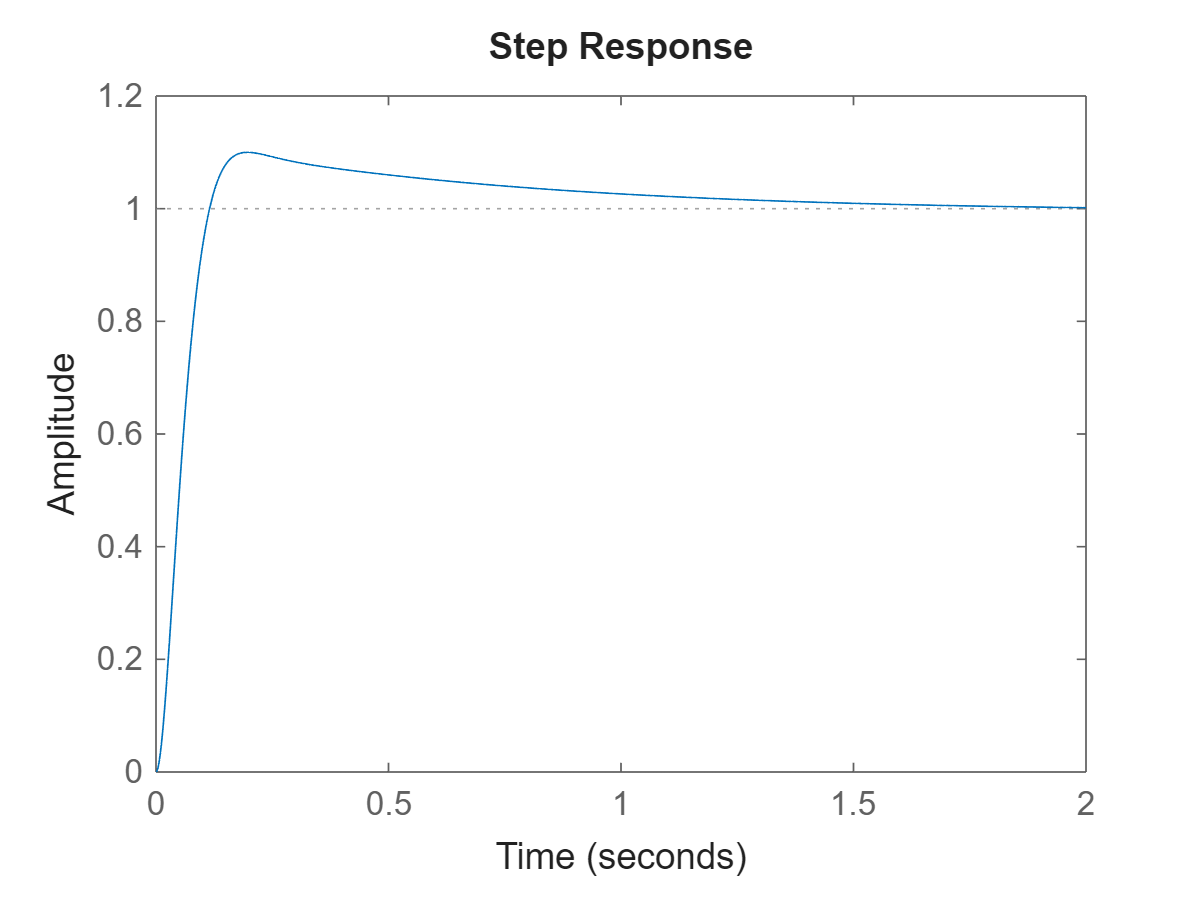


C = Kp + Ki/s + Kd*s;

Ts = feedback(Gs_new*C, 1);
step(Ts)


[Y, t] = step(Ts, 2); 
ess = abs(1 - Y(end))

ess = 0.0017

stepinfo(Ts)

ans = struct with fields:
         RiseTime: 0.0769
    TransientTime: 1.1461
     SettlingTime: 1.1461
      SettlingMin: 0.9089
      SettlingMax: 1.1000
        Overshoot: 10.0009
       Undershoot: 0
             Peak: 1.1000
         PeakTime: 0.1972


Tuning the x,y value

Ku_xy = 250; Tu_xy = 1.778;

Kp_xy = 8

Kp_xy = 8

Ki_xy = 0.5

Ki_xy = 0.5000

Kd_xy = 15

Kd_xy = 15

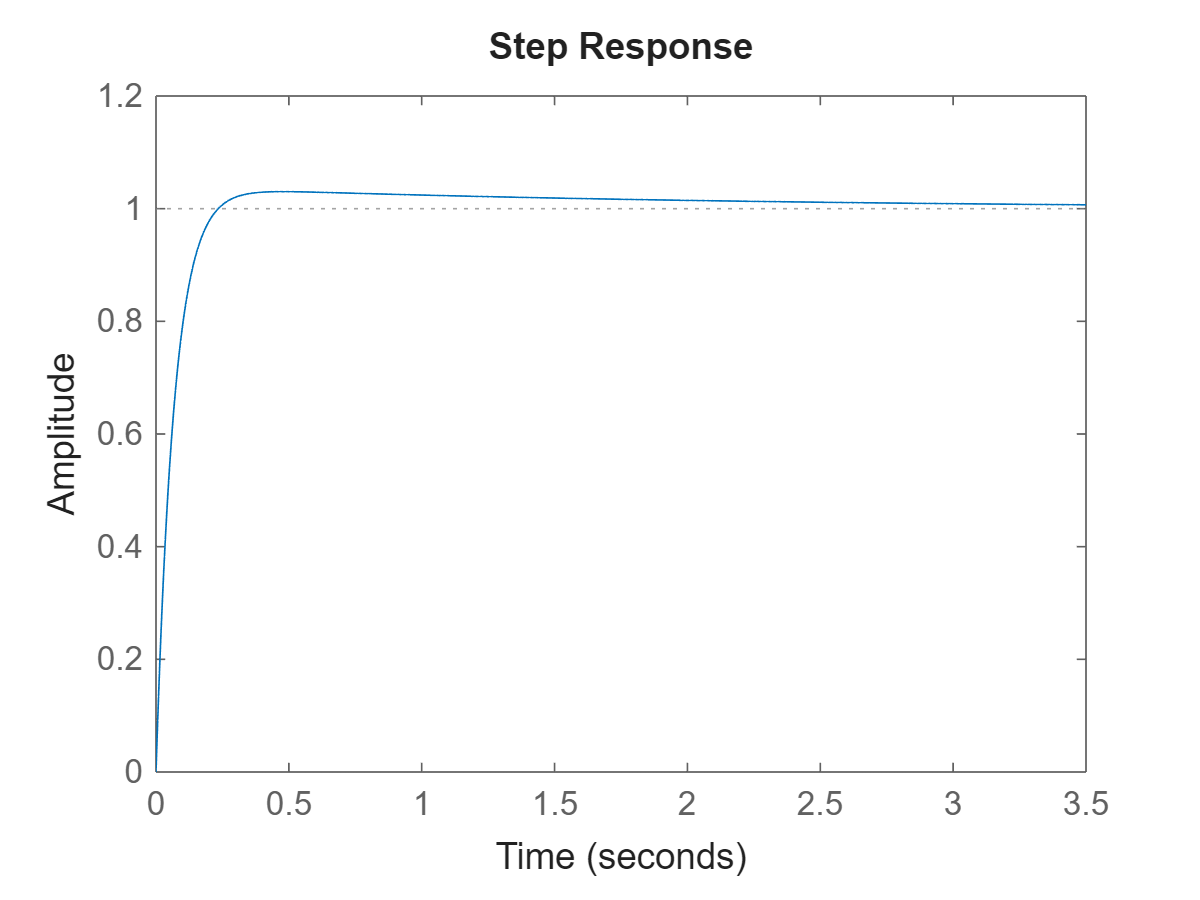

%Kp_xy = 0.6*Ku_xy 
%Ki_xy = 1.2*(Ku_xy/Tu_xy) 
%Kd_xy = (0.6/8)*Ku_xy*Tu_xy

Gs_xy = 1/s^2; %this means there is no mass involved in the lateral motion
C_xy = Kp_xy + Ki_xy/s + Kd_xy*s;

Ts_xy = feedback(Gs_xy*C_xy, 1);
step(Ts_xy)


[Y, t] = step(Ts_xy, 2); 
ess = abs(1 - Y(end))

ess = 0.0147

stepinfo(Ts_xy)

ans = struct with fields:
         RiseTime: 0.1333
    TransientTime: 1.3841
     SettlingTime: 1.3841
      SettlingMin: 0.9060
      SettlingMax: 1.0302
        Overshoot: 3.0214
       Undershoot: 0
             Peak: 1.0302
         PeakTime: 0.4781
